# Modelagem cinemática de um mecanismo de 3 graus de liberdade em cadeia cinemática aberta

### Desenho do mecanismo, suas variáveis e parâmetros.

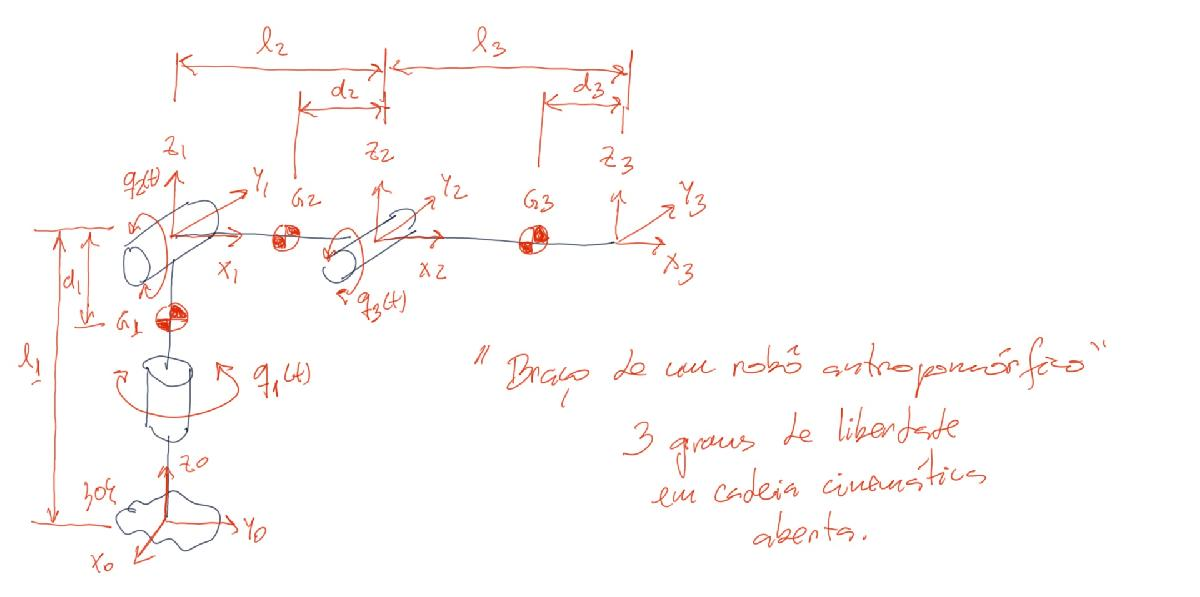

Figura 1 - Esquema do mecanismo de 3 graus de liberdade.

### Definição das variáveis e dos parâmetros do modelo

#### Comprimentos dos Elos:

syms L1 L2 L3

#### Coordenadas dos centros de massa:

syms d1 d2 d3

#### Coordenadas genaralizadas do mecanismo:

syms q1 q2 q3
syms dq1 dq2 dq3
syms d2q1 d2q2 d2q3
q = [q1; q2; q3];
dq = [dq1; dq2; dq3];
d2q = [d2q1; d2q2; d2q3];

### Estudar as transformações entre os referenciais

#### Diagrama de transformações

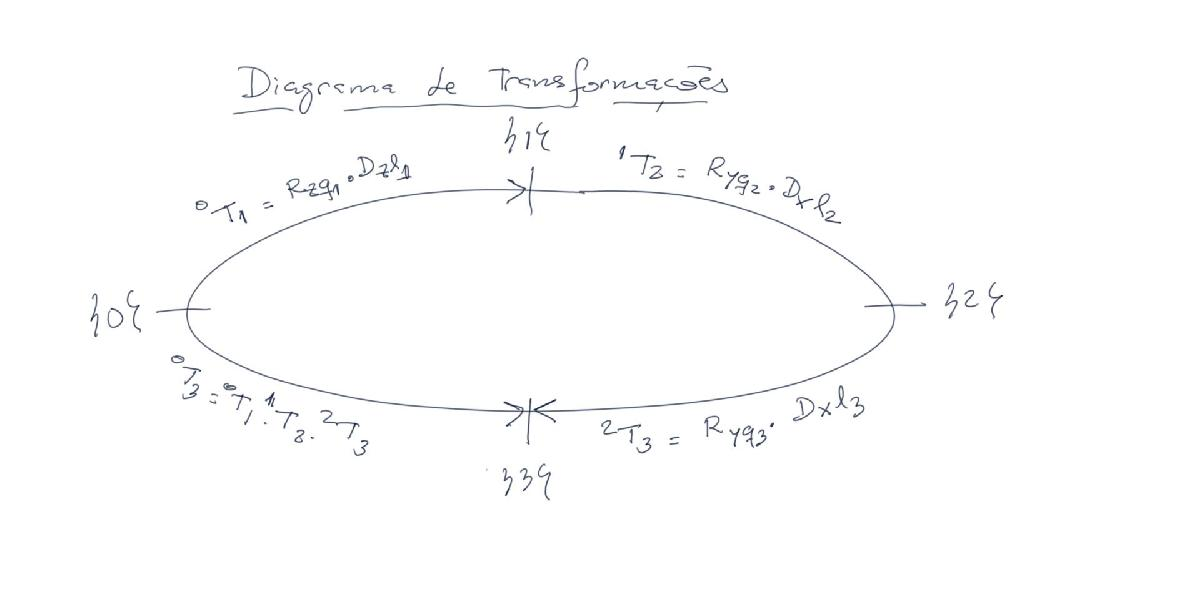

Figura 2 - Diagrama de transformações.

#### Definir as matrizes de transformação conforme o diagrama da Figura 1.

#### Transformação entre os referenciais {0} e {1}:

R1_0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1];
D1_0 = [1 0 0 0; 0 1 0 0; 0 0 1 L1; 0 0 0 1];
T1_0 = R1_0*D1_0

$$T1\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Transformação entre os referenciais {1} e {2}:

R2_1 = [cos(q2) 0 sin(q2) 0; 0 1 0 0; -sin(q2) 0 cos(q2) 0; 0 0 0 1];
D2_1 = [1 0 0 L2; 0 1 0 0; 0 0 1 0; 0 0 0 1];
T2_1 = R2_1*D2_1

$$T2\_1 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{2}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & -L_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Transformação entre os referenciais {2} e {3}:

R3_2 = [cos(q3) 0 sin(q3) 0; 0 1 0 0; -sin(q3) 0 cos(q3) 0; 0 0 0 1];
D3_2 = [1 0 0 L3; 0 1 0 0; 0 0 1 0; 0 0 0 1];
T3_2 = R3_2*D3_2

$$T3\_2 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & L_{3}\,\cos\left(q_{3}\right)\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & -L_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Transformações entre todos os referenciais:

T2_0 = T1_0*T2_1

$$T2\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & L_{1}-L_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3_0 = T2_0*T3_2

$$T3\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+L_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-L_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+L_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-L_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ -\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & L_{1}-L_{2}\,\sin\left(q_{2}\right)-L_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-L_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Determinar o vetor posição até a origem dos referenciais, com relação ao referencial inercial.

#### Origem do referencial {1} com relação ao referencial {0}:

p1_0 = T1_0(1:3,4)

$$p1\_0 = \left(\begin{array}{c} 0\\ 0\\ L_{1} \end{array}\right)$$

#### Origem do referencial {2} com relação ao referencial {0}:

p2_0 = T2_0(1:3,4)

$$p2\_0 = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ L_{1}-L_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

#### Origem do referencial {3} com relação ao referencial {0}:

p3_0 = simplify(T3_0(1:3,4))

$$p3\_0 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)\,\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)\\ L_{1}-L_{3}\,\sin\left(q_{2}+q_{3}\right)-L_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

### Posição dos centros de massa, com relação ao referencial inercial.

#### Centro de massa do corpo 1 (G1):

pG1_1 = [0; 0; -d1; 1];
aux = T1_0*pG1_1;
pG1_0 = aux(1:3)

$$pG1\_0 = \left(\begin{array}{c} 0\\ 0\\ L_{1}-d_{1} \end{array}\right)$$

clear aux

#### Centro de massa do corpo 2 (G2):

pG2_2 = [-d2; 0; 0; 1];
aux = T2_0*pG2_2;
pG2_0 = aux(1:3)

$$pG2\_0 = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-d_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ L_{1}-L_{2}\,\sin\left(q_{2}\right)+d_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

clear aux

#### Centro de massa do corpo 3 (G3):

pG3_3 = [-d3; 0; 0; 1];
aux = T3_0*pG3_3;
pG3_0 = simplify(aux(1:3))

$$pG3\_0 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)\,\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)\\ L_{1}-L_{3}\,\sin\left(q_{2}+q_{3}\right)+d_{3}\,\sin\left(q_{2}+q_{3}\right)-L_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

clear aux

### Velocidades e acelerações, lineares e angulares, dos referenciais móveis, com relação ao referencial inercial.

#### Velocidade linear do {1} :

JL1_0 = jacobian(p1_0,q);
v1_0 = JL1_0*dq

$$v1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

#### Velocidade angular do {1}:

JA1_0 = [T1_0(1:3,3) zeros(3,1) zeros(3,1)];
w1_0 = JA1_0*dq

$$w1\_0 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{dq}}_{1} \end{array}\right)$$

#### Aceleração linear do {1}:

dJL1_0 = [jacobian(JL1_0(:,1),q)*dq jacobian(JL1_0(:,2),q)*dq jacobian(JL1_0(:,3),q)*dq];
dv1_0 = JL1_0*d2q + dJL1_0*dq

$$dv1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

#### Aceleração angular do {1}:

dJA1_0 = [jacobian(JA1_0(:,1),q)*dq jacobian(JA1_0(:,2),q)*dq jacobian(JA1_0(:,3),q)*dq];
dw1_0 = JA1_0*d2q + dJA1_0*dq

$$dw1\_0 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{d2q}}_{1} \end{array}\right)$$

#### Velocidade linear do {2} :

JL2_0 = jacobian(p2_0,q);
v2_0 = JL2_0*dq

$$v2\_0 = \left(\begin{array}{c} -L_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ L_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

#### Velocidade angular do {2}:

JA2_0 = [T1_0(1:3,3) T2_0(1:3,2) zeros(3,1)];
w2_0 = JA2_0*dq

$$w2\_0 = \left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1} \end{array}\right)$$

#### Aceleração linear do {2}:

dJL2_0 = [jacobian(JL2_0(:,1),q)*dq jacobian(JL2_0(:,2),q)*dq jacobian(JL2_0(:,3),q)*dq];
dv2_0 = JL2_0*d2q + dJL2_0*dq

$$dv2\_0 = \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,\left(L_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-{\mathrm{dq}}_{2}\,\left(L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-L_{2}\,{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-L_{2}\,{\mathrm{d2q}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-L_{2}\,{\mathrm{d2q}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ L_{2}\,{\mathrm{d2q}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\left(L_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)-{\mathrm{dq}}_{1}\,\left(L_{2}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-L_{2}\,{\mathrm{d2q}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ L_{2}\,{{\mathrm{dq}}_{2}}^{2}\,\sin\left(q_{2}\right)-L_{2}\,{\mathrm{d2q}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

#### Aceleração angular do {2}:

dJA2_0 = [jacobian(JA2_0(:,1),q)*dq jacobian(JA2_0(:,2),q)*dq jacobian(JA2_0(:,3),q)*dq];
dw2_0 = JA2_0*d2q + dJA2_0*dq

$$dw2\_0 = \left(\begin{array}{c} -{\mathrm{d2q}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{d2q}}_{2}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{d2q}}_{1} \end{array}\right)$$

#### Velocidade linear do {3} :

JL3_0 = jacobian(p3_0,q);
v3_0 = JL3_0*dq

$$v3\_0 = \begin{array}{l} \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sigma_{2}-L_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sigma_{2}-L_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ -{\mathrm{dq}}_{2}\,\sigma_{1}-L_{3}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=L_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{2}\,\sin\left(q_{2}\right) \end{array}$$

#### Velocidade angular do {3}:

JA3_0 = [T1_0(1:3,3) T2_0(1:3,2) T3_0(1:3,2)];
w3_0 = JA3_0*dq

$$w3\_0 = \left(\begin{array}{c} -{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{3}\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)+{\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1} \end{array}\right)$$

#### Aceleração linear do {3}:

dJL3_0 = [jacobian(JL3_0(:,1),q)*dq jacobian(JL3_0(:,2),q)*dq jacobian(JL3_0(:,3),q)*dq];
dv3_0 = JL3_0*d2q + dJL3_0*dq

#### Aceleração angular do {3}:

dJA3_0 = [jacobian(JA3_0(:,1),q)*dq jacobian(JA3_0(:,2),q)*dq jacobian(JA3_0(:,3),q)*dq];
dw3_0 = JA3_0*d2q + dJA3_0*dq

$$dw3\_0 = \left(\begin{array}{c} -{\mathrm{d2q}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{d2q}}_{3}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\\ {\mathrm{d2q}}_{2}\,\cos\left(q_{1}\right)+{\mathrm{d2q}}_{3}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\sin\left(q_{1}\right)\\ {\mathrm{d2q}}_{1} \end{array}\right)$$

### Velocidades e acelerações lineares dos centros de massa.

#### Velocidade linear do ponto G1:

JLG1_0 = jacobian(pG1_0,q);
vG1_0 = JLG1_0*dq

$$vG1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

#### Aceleração linear do ponto G1:

dJLG1_0 = [jacobian(JLG1_0(:,1),q)*dq jacobian(JLG1_0(:,2),q)*dq jacobian(JLG1_0(:,3),q)*dq];
dvG1_0 = JLG1_0*d2q + dJLG1_0*dq

$$dvG1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

#### Velocidade linear do ponto G2:

JLG2_0 = jacobian(pG2_0,q);
vG2_0 = JLG2_0*dq

$$vG2\_0 = \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,\left(L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)-{\mathrm{dq}}_{2}\,\left(L_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ {\mathrm{dq}}_{1}\,\left(L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-d_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\right)-{\mathrm{dq}}_{2}\,\left(L_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -{\mathrm{dq}}_{2}\,\left(L_{2}\,\cos\left(q_{2}\right)-d_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$

#### Aceleração linear do ponto G2:

dJLG2_0 = [jacobian(JLG2_0(:,1),q)*dq jacobian(JLG2_0(:,2),q)*dq jacobian(JLG2_0(:,3),q)*dq];
dvG2_0 = JLG2_0*d2q + dJLG2_0*dq

$$dvG2\_0 = \begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{1}\,\sigma_{4}\right)-{\mathrm{d2q}}_{2}\,\sigma_{3}-{\mathrm{d2q}}_{1}\,\sigma_{2}+{\mathrm{dq}}_{2}\,\left({\mathrm{dq}}_{1}\,\sigma_{1}-{\mathrm{dq}}_{2}\,\sigma_{4}\right)\\ {\mathrm{d2q}}_{1}\,\sigma_{4}-{\mathrm{dq}}_{1}\,\left({\mathrm{dq}}_{1}\,\sigma_{2}+{\mathrm{dq}}_{2}\,\sigma_{3}\right)-{\mathrm{dq}}_{2}\,\left({\mathrm{dq}}_{1}\,\sigma_{3}+{\mathrm{dq}}_{2}\,\sigma_{2}\right)-{\mathrm{d2q}}_{2}\,\sigma_{1}\\ {{\mathrm{dq}}_{2}}^{2}\,\left(L_{2}\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{2}\right)\right)-{\mathrm{d2q}}_{2}\,\left(L_{2}\,\cos\left(q_{2}\right)-d_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=L_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=L_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-d_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

#### Velocidade linear do ponto G3:

JLG3_0 = jacobian(pG3_0,q);
vG3_0 = JLG3_0*dq

$$vG3\_0 = \begin{array}{l} \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sigma_{2}-{\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\,\sigma_{3}\\ {\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\sigma_{1}-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sigma_{2}-{\mathrm{dq}}_{3}\,\sin\left(q_{1}\right)\,\sigma_{3}\\ -{\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{3}\,\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{3}\,\cos\left(q_{2}+q_{3}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\cos\left(q_{2}+q_{3}\right)-d_{3}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=L_{3}\,\sin\left(q_{2}+q_{3}\right)-d_{3}\,\sin\left(q_{2}+q_{3}\right)+L_{2}\,\sin\left(q_{2}\right)\\ \sigma_{3}=L_{3}\,\sin\left(q_{2}+q_{3}\right)-d_{3}\,\sin\left(q_{2}+q_{3}\right) \end{array}$$

#### Aceleração linear do ponto G3:

dJLG3_0 = [jacobian(JLG3_0(:,1),q)*dq jacobian(JLG3_0(:,2),q)*dq jacobian(JLG3_0(:,3),q)*dq];
dvG3_0 = JLG3_0*d2q + dJLG3_0*dq